% Discrete Step Response Analysis with Custom Metrics
% Designed for hardware implementation with small oscillations
% SETPOINT FIXED AT 50

% Define setpoint at the beginning (FIXED VALUE)
SETPOINT = 50; % This is now the reference for all calculations

% Extract time and signal data from the structure
time = Tuned_Lead_RPM_Input.time;
signal = Tuned_Lead_RPM_Input.signals.values;

% If multiple signals, select the first one (modify index as needed)
if size(signal, 2) > 1
    signal = signal(:, 1);
    fprintf('Multiple signals detected. Analyzing first signal.\n');
end

% Plot the step response
figure;
plot(time, signal, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Discrete Step Response Analysis');

% Custom analysis for discrete/hardware systems
% Parameters for analysis
settling_tolerance = 0.05; % 5% settling band (adjustable)
rise_percentage_low = 0.1;  % 10% for rise time start
rise_percentage_high = 0.9; % 90% for rise time end

% Calculate steady-state value (average of last 20% of data)
steady_state_region = round(0.8 * length(signal)):length(signal);
steady_state_value = mean(signal(steady_state_region));

% Calculate peak value and time
[peak_value, peak_idx] = max(signal);
peak_time = time(peak_idx);

% Calculate overshoot (referenced to SETPOINT)
overshoot_percent = ((peak_value - SETPOINT) / SETPOINT) * 100;
if overshoot_percent < 0
    overshoot_percent = 0; % No overshoot if peak is below setpoint
end

% Calculate undershoot (referenced to SETPOINT)
min_value = min(signal);
undershoot_percent = ((SETPOINT - min_value) / SETPOINT) * 100;
if undershoot_percent < 0
    undershoot_percent = 0; % No undershoot
end

% Calculate rise time (10% to 90% of SETPOINT)
rise_start_value = SETPOINT * rise_percentage_low;
rise_end_value = SETPOINT * rise_percentage_high;

% Find indices for rise time calculation
rise_start_idx = find(signal >= rise_start_value, 1, 'first');
rise_end_idx = find(signal >= rise_end_value, 1, 'first');

if ~isempty(rise_start_idx) && ~isempty(rise_end_idx)
    rise_time = time(rise_end_idx) - time(rise_start_idx);
else
    rise_time = NaN;
    fprintf('Warning: Could not calculate rise time\n');
end

% Calculate settling time with tolerance referenced to SETPOINT
settling_upper = SETPOINT * (1 + settling_tolerance);
settling_lower = SETPOINT * (1 - settling_tolerance);

% Find last time signal exits settling band
settling_violations = find(signal > settling_upper | signal < settling_lower);
if ~isempty(settling_violations)
    last_violation_idx = settling_violations(end);
    settling_time = time(last_violation_idx);
else
    settling_time = 0; % Signal never left settling band
end

% Calculate steady-state error (using fixed SETPOINT)
steady_state_error_abs = abs(SETPOINT - steady_state_value);
steady_state_error_percent = (steady_state_error_abs / SETPOINT) * 100;

% Calculate additional metrics for discrete systems
% RMS of oscillations around SETPOINT in steady-state region
steady_state_rms = rms(signal(steady_state_region) - SETPOINT);

% Maximum deviation from SETPOINT in steady-state region
steady_state_max_dev = max(abs(signal(steady_state_region) - SETPOINT));

% Display results
fprintf('\n=== Discrete Step Response Performance Metrics ===\n');


=== Discrete Step Response Performance Metrics ===


fprintf('SETPOINT (Reference): %.1f\n', SETPOINT);

SETPOINT (Reference): 50.0


fprintf('Rise Time (10%% to 90%%): %.4f seconds\n', rise_time);

Rise Time (10% to 90%): 0.0700 seconds


fprintf('Settling Time (%.0f%% band): %.4f seconds\n', settling_tolerance*100, settling_time);

Settling Time (5% band): 0.8700 seconds


fprintf('Peak Value: %.4f\n', peak_value);

Peak Value: 61.5385


fprintf('Peak Time: %.4f seconds\n', peak_time);

Peak Time: 0.6600 seconds


fprintf('Overshoot: %.2f%%\n', overshoot_percent);

Overshoot: 23.08%


fprintf('Undershoot: %.2f%%\n', undershoot_percent);

Undershoot: 100.00%


fprintf('Steady-State Value: %.4f\n', steady_state_value);

Steady-State Value: 50.0005


fprintf('Steady-State Error (absolute): %.4f\n', steady_state_error_abs);

Steady-State Error (absolute): 0.0005


fprintf('Steady-State Error (%%): %.2f%%\n', steady_state_error_percent);

Steady-State Error (%): 0.00%


fprintf('Steady-State RMS Deviation: %.4f\n', steady_state_rms);

Steady-State RMS Deviation: 0.5495


fprintf('Steady-State Max Deviation: %.4f\n', steady_state_max_dev);

Steady-State Max Deviation: 0.5495



% Stability assessment (using SETPOINT as reference)
if settling_time > 0.9 * time(end)
    stability_status = 'Marginally Stable (long settling)';
elseif steady_state_max_dev > 0.1 * SETPOINT
    stability_status = 'Marginally Stable (oscillatory)';
else
    stability_status = 'Stable';
end
fprintf('Stability Assessment: %s\n', stability_status);

Stability Assessment: Stable


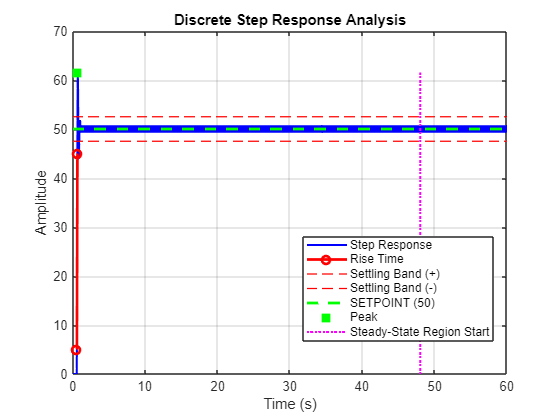


% Enhanced plotting with annotations
hold on;

% Mark rise time region
if ~isnan(rise_time)
    plot([time(rise_start_idx), time(rise_end_idx)], ...
         [rise_start_value, rise_end_value], 'ro-', 'MarkerSize', 6, 'LineWidth', 2);
end

% Mark settling band (referenced to SETPOINT)
plot([0, time(end)], [settling_upper, settling_upper], 'r--', 'LineWidth', 1);
plot([0, time(end)], [settling_lower, settling_lower], 'r--', 'LineWidth', 1);
plot([0, time(end)], [SETPOINT, SETPOINT], 'g--', 'LineWidth', 2);

% Mark peak
plot(peak_time, peak_value, 'gs', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% Mark steady-state region
steady_state_start_time = time(steady_state_region(1));
plot([steady_state_start_time, steady_state_start_time], [min(signal), max(signal)], ...
     'm:', 'LineWidth', 1.5);

legend('Step Response', 'Rise Time', 'Settling Band (+)', 'Settling Band (-)', ...
       'SETPOINT (50)', 'Peak', 'Steady-State Region Start', 'Location', 'best');
hold off;


% Store all metrics in a structure
metrics = struct();
metrics.Setpoint = SETPOINT;
metrics.RiseTime = rise_time;
metrics.SettlingTime = settling_time;
metrics.SettlingTolerance = settling_tolerance;
metrics.Peak = peak_value;
metrics.PeakTime = peak_time;
metrics.Overshoot = overshoot_percent;
metrics.Undershoot = undershoot_percent;
metrics.SteadyStateValue = steady_state_value;
metrics.SteadyStateError = steady_state_error_abs;
metrics.SteadyStateErrorPercent = steady_state_error_percent;
metrics.SteadyStateRMS = steady_state_rms;
metrics.SteadyStateMaxDeviation = steady_state_max_dev;
metrics.StabilityStatus = stability_status;

fprintf('\nAll metrics saved to ''metrics'' structure.\n');


All metrics saved to 'metrics' structure.


fprintf('Use ''metrics'' to access individual values (e.g., metrics.RiseTime)\n');

Use 'metrics' to access individual values (e.g., metrics.RiseTime)



% Optional: Display the structure fields
fprintf('\nAvailable metrics fields:\n');


Available metrics fields:


disp(fieldnames(metrics));

    {'Setpoint'               }
    {'RiseTime'               }
    {'SettlingTime'           }
    {'SettlingTolerance'      }
    {'Peak'                   }
    {'PeakTime'               }
    {'Overshoot'              }
    {'Undershoot'             }
    {'SteadyStateValue'       }
    {'SteadyStateError'       }
    {'SteadyStateErrorPercent'}
    {'SteadyStateRMS'         }
    {'SteadyStateMaxDeviation'}
    {'StabilityStatus'        }




% Additional diagnostic information
fprintf('\n=== Diagnostic Information ===\n');


=== Diagnostic Information ===


fprintf('Signal length: %d samples\n', length(signal));

Signal length: 6001 samples


fprintf('Time span: %.2f seconds\n', time(end) - time(1));

Time span: 60.00 seconds


fprintf('Average sampling rate: %.2f Hz\n', length(signal) / (time(end) - time(1)));

Average sampling rate: 100.02 Hz


fprintf('Steady-state region: samples %d to %d\n', steady_state_region(1), steady_state_region(end));

Steady-state region: samples 4801 to 6001
